clc,clear,close all
f = @(x,t) -x.^2 + (20*cos(pi/100*t)+20)*x - (10 + 10*cos(pi/100*t))^2 + 5*sin(pi/100*t) + 5;
xlow = -10;
xhigh = 30;
t = 0;
es = 1e-9;
alpha = 0.67;
disp('GoldenMethod caculate result')

GoldenMethod caculate result


[xm,fm,iter] = GoldenMethod(xlow,xhigh,es,f,t)

xm = 20.0000

fm = 5.0000

iter = 50

disp('NativeMethod caculate result')

NativeMethod caculate result


[xm,fm,iter] = NativeMethod(xlow,xhigh,es,f,t,alpha)

xm = 20.0000

fm = 5

iter = 61


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc,clear,close all
f = @(x,t) -x.^2 + (20*cos(pi/100*t)+20)*x - (10 + 10*cos(pi/100*t))^2 + 5*sin(pi/100*t) + 5;
xlow = -10;
xhigh = 30;
es = 1e-9;
t = 0:0.1:150;
n = length(t);
alpha = 0.67;
xm_GoldenMethod = zeros(1,n);
fm_GoldenMethod = zeros(1,n);
tic
for i = 1:n
    tt = t(i);
    [xm,fm,~] = GoldenMethod(xlow,xhigh,es,f,tt);
    xm_GoldenMethod(i) = xm;
    fm_GoldenMethod(i) = fm;
end
toc

历时 0.034661 秒。


xm_NativeMethod = zeros(1,n);
fm_NativeMethod = zeros(1,n);
tic
for i = 1:n
    tt = t(i);
    [xm,fm,~] = NativeMethod(xlow,xhigh,es,f,tt,alpha);
    xm_NativeMethod(i) = xm;
    fm_NativeMethod(i) = fm;
end
toc

历时 0.034224 秒。


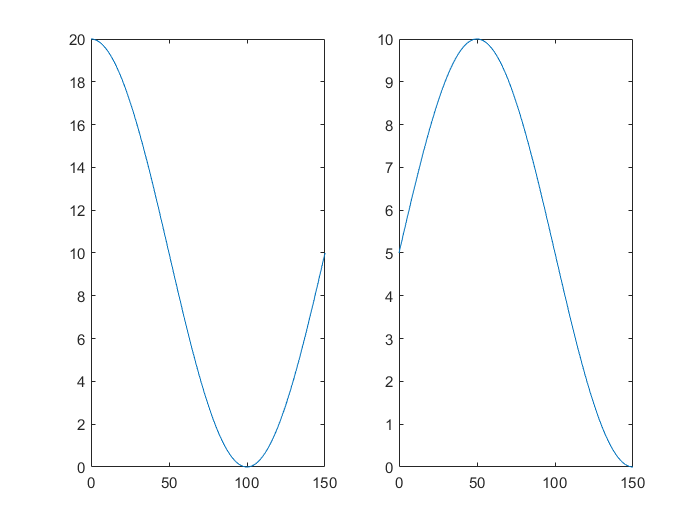

subplot(1,2,1)
plot(t,xm_GoldenMethod)
subplot(1,2,2)
plot(t,fm_GoldenMethod)